# Nenana Engineering Challenge (2/2)

**Before you get started:**

This live script is intended to be used with the code hidden. On **View** tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**. Alternately, select **Hide Code **using the icon 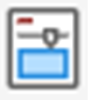 at the top right of the Live Editor pane. 

  For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one, including running the code blocks in it.

  **Pro-tip**. The   **Run** command runs each line of code in order from the beginning until the last line in the script. You can clear the output in the script in the **View** tab by clicking **Clear all Output**.

## 4. Plan: Select a Promising Solution.

Using the linear model, which set of dates would you choose to reflect the most recent trends.

### a. Import Data. 

  **Try **Press the 'Import Data' button below to import the data. You can learn more about the [interactive 'Button' Control](https://www.mathworks.com/help/matlab/matlab_prog/add-interactive-controls-to-a-live-script.html) here.

 
% Insert Import Data Task here.

% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 5);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Year", "DecimalDayOfYear", "Month", "Day", "Time"];
opts.VariableTypes = ["double", "double", "categorical", "double", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Time", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Month", "Time"], "EmptyFieldRule", "auto");

% Import the data
NenanaIceClassic_1917_20212 = readtable("NenanaIceClassic_1917-2021.csv", opts);

% Convert to output type
Year = NenanaIceClassic_1917_20212.Year;
DecimalDayOfYear = NenanaIceClassic_1917_20212.DecimalDayOfYear;
Month = NenanaIceClassic_1917_20212.Month;
Day = NenanaIceClassic_1917_20212.Day;
Time = NenanaIceClassic_1917_20212.Time;

% Clear temporary variables
clear NenanaIceClassic_1917_20212

% Clear temporary variables
clear opts

% Display results
% Year, DecimalDayOfYear, Month, Day, Time
disp('Data loaded.')

### b. Plot and Fit Linear Model to Data for 1917 - 2021. 

  **Try**. Press the 'Plot & Fit Data' button below to plot and fit the full range of data to a linear model. 

% DO NOT MODIFY
 
% Fit: "All Data - 1917-2021".
[xData, yData] = prepareCurveData( Year, DecimalDayOfYear );

% Set up fittype and options.
ft = fittype( "poly1" );

% Fit model to data.
[fitresult, ~] = fit( xData, yData, ft );

% Plot fit with data.

h = plot( fitresult, xData, yData);
title("1917 - 2021")
legend( h, "DecimalDayOfYear vs. Year", "Fitted Curve", "Location", "best", "Interpreter", "none" );
% Label axes
xlabel( "Year", "Interpreter", "none" );
ylabel( "DecimalDayOfYear", "Interpreter", "none" );



### c. Evaluate Options. **Create a fit by choosing a range of dates. **

Use the slider below to first select the Start Date and the End Date of your data range. Adjust the sliders for the Start Date, the End Date, and then press the 'Plot fit for first set of data ranges' to plot the new set of start to end dates. All of the data from 1917 - 2021 will be plotted, but the date range you have selected  will be shown as blue circles while the excluded data will be plotted and shown as green plus signs.  

To help you visually determine the adequacy of your chosen date range, the DecimalDayOfYear for 2023 (122.76 DecimalDayOfYear) is plotted along with the 1917 - 2021 dates. 

  **Try**. Adjust the slider below to select date ranges for your linear model. 

% Fit: "Data Range 2".
[xData, yData] = prepareCurveData(Year,DecimalDayOfYear );

% Set up fittype and options.
ft = fittype( "poly1" );
bds = sort([1969, 2009]);
rangestart2=bds(1);
start=num2str(rangestart2);
rangeend2= bds(2);
last =num2str(rangeend2);

% Plot Data range and new line
excludedPoints = (xData<rangestart2) | (xData>rangeend2) ;
opts = fitoptions( "Method", "LinearLeastSquares" );
opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult2, ~] = fit( xData, yData, ft, opts );

% Plot fit with data.
scatter(2023,122.76,20,"magenta","filled")
hold on
h = plot( fitresult2, xData, yData, excludedPoints );
title("Date Range " + rangestart2 + "-" + rangeend2);
legend("2023", "1917 - 2021 Data", "Excluded DecimalDayOfYear vs. Year", "Linear Fit for Date Range " + rangestart2 + " - " + rangeend2, "Location", "SouthWest", "Interpreter", "none" );
% Label axes
xlabel( "Year", "Interpreter", "none" );
ylabel( "DecimalDayOfYear", "Interpreter", "none" );

hold off

% Display the formatted string and the numeric value
m = fitresult2.p1;
b =fitresult2.p2;
disp("The slope is " + m + " and the y-intercept is " + b )

## 5. Create:Build a Prototype.

 **Reflect**. Based on the your results in section 4, which set of dates seem like the best fit?

## 6. Test and Evaluate Prototype.

In this section, you will evaluate the performance of your selected mathematical model to evaluate how well your model predicts historical data and future data.

### ** Compare your model to historical data (1917 - 2021) graphically and statistically**

Use the new linear model from above to evaluate how well your model fits historical data. 

**R-squared**, also known as the coefficient of determination, is a statistical measure that is commonly used to evaluate how well a regression model fits a given set of data. In practical terms, an r-squared value close to 1 indicates that the regression model is a good fit for the data and can be used to make accurate predictions. Conversely, an r-squared value close to 0 indicates that the regression model is a poor fit for the data and should not be used for making predictions.

In summary, r-squared is a measure of how well a regression model fits a set of data. It ranges from 0 to 1, with values closer to 1 indicating a better fit, and values closer to 0 indicating a poorer fit

  **Try**. Select your date ranges from the previous section to evaluate the R-squared value and the Percent Error for your chosen date range.Select the year below:

[xData, yData] = prepareCurveData(Year,DecimalDayOfYear );

% Set up fittype and options.
ft = fittype( "poly1" );
bds = sort([1977, 1973]);
rangestart2=bds(1);
start=num2str(rangestart2);
rangeend2= bds(2);
last =num2str(rangeend2);

% Plot Data range and new line
excludedPoints = (xData<rangestart2) | (xData>rangeend2) ;
opts = fitoptions( "Method", "LinearLeastSquares" );
opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult2, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
h = plot( fitresult2, xData, yData, excludedPoints );
title("Date Range " + rangestart2 + "-" + rangeend2);
legend("1917 - 2021 Data", "Excluded DecimalDayOfYear vs. Year", "Linear Fit for Date Range " + rangestart2 + " - " + rangeend2, "Location", "SouthWest", "Interpreter", "none" );
% Label axes
xlabel( "Year", "Interpreter", "none" );
ylabel( "DecimalDayOfYear", "Interpreter", "none" );

hold off

  **Try**. Determine the slope, y-intercept and R-squared value for your chosen date range. Learn more about [R-squared values](https://www.mathworks.com/help/stats/coefficient-of-determination-r-squared.html?searchHighlight=R%20squared&s_tid=srchtitle_support_results_1_R%20squared) here. Select the year below:


predyear = 1983;
y1 = fitresult2.p1*predyear+fitresult2.p2;
idx = find(Year == predyear);

PercentError=((DecimalDayOfYear(idx)-y1)/DecimalDayOfYear(idx))*100;

% Format the number with two decimal places using num2str
formatted_str = num2str(PercentError, '%.2f');

% Convert the formatted string to a numeric value (optional)
formatted_num = str2double(formatted_str);

% Calculate Rsquared value
Rsquared = gof.rsquare;

% Calculate slope and y-intercept
m = fitresult2.p1;
b = fitresult2.p2;

% Display the formatted string and the numeric value
disp("The slope is " + m + " and the y-intercept is " + b )
disp("The percentage error between the actual and predicted time of breakup in " + predyear +  newline + " is " +  formatted_str )
disp("The rsquared value between the actual and predicted time of breakup in " + predyear +  newline + " is " +  Rsquared )

  **Try**. Enter the errors for the different models for at least 3 distinct date ranges in the table below:

 **Reflect**. Based on the R-squared values and Percent Error, which model seems like the best fit? 

 **Reflect**. Which model is most suitable for predicting the exact date(DecimalDayOfYear) of ice breakup on the Tanana River? Explain your reasoning.

  **Reflect**. What are some factors that your models may have overlooked, including considerations like weather patterns, ice thickness variations, or fluctuations in river flow?

### [Return to Nenana 1 - 3](matlab:open('./Nenana1_3d.mlx'))

% Functions

function [fitresult, gof] = createFit(Year, DecimalDayOfYear)
[xData, yData] = prepareCurveData( Year, DecimalDayOfYear );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

end

